### Define if the process will involve parallel looping or not.

clear; close all; clc
% Define if the simulation will be run in parallel-------------------------------
% It is also needed to manually change the inner loop 'for' to 'parfor'!
useParallel = true;
% Progress bar ------------------------------------------------------------------
if ~useParallel
    f = waitbar(0, 'Starting');
end

### Setup variables

format long
warning('on')

% Simulation (defined by the user) --------------------------------------------------------------
% Pw_user_dBm = -6:2:6;                      % Power per user in dBm
% Packets = [100 125 150 175 200 225 250];          % Number of Packets to Send


% Pw_user_dBm = 0:1:7;
% Packets = [100 200 200 400 400 600 600 800];

% Pw_user_dBm = 0:1:10;
% Packets = [20 40 60 100 100 100 150 200 300 400 500];

Pw_user_dBm = 3:1:5;  % current TX power dBm 
Packets = [10 20 30];      
% Pw_user_dBm = 3:1:4;
% Packets = [1000 1000];

if length(Packets) ~= length(Pw_user_dBm)
   error('Error Packets and Pw_user_dBm vectors must have the same size')
end
% System Initialization
[sys,enviroment,estimation,idd1,idd3] = initializeSystem_Extensions_1024_VTC_3_layers(Pw_user_dBm);


% Methods Evaluated in Simulation ---------------------------------------------------------------
methods = [
"Initial"
"benckmark"
"PL"
];

% Auxiliar variables ---------------------------------------------------------------------------
PacketBitLength = sys.PacketDataLength*sys.n_tx;
DataLength = (sys.PacketDataLength-estimation.bd*sys.M_ORD)*sys.n_tx;
numberofmethods = length(methods);
numPWR = length(Pw_user_dBm);        
DateI = datetime('now');

% Variables Initialization----------------------------------------------------------------------
RsumVec = zeros(numberofmethods,numPWR);
BerVec  = zeros(numberofmethods,numPWR);
NmseVec  = zeros(numberofmethods,numPWR);

[W_L,W_0,~] = generate_WSIM(sys.n_layers,sys.lambda,sys.Nc,sys.n_rx);

### **Main Function **

for pwr = 1:numPWR
    printStatus(pwr,Pw_user_dBm)
    % Auxiliar variables in the loop ------------------------------
    RsumVec_aux = zeros(numberofmethods,length(Packets));
    BerVec_aux = zeros(numberofmethods, length(Packets));
    NmseVec_aux = zeros(numberofmethods, length(Packets));

    parfor NumPackets = 1:Packets(pwr)
        % init variables ------------------------------------------
        Ber = zeros(length(methods),1);
        Rsum = zeros(length(methods),1);
        Nmse = zeros(length(methods),1);

        % Channel coefficients generation ----------------------------------------------------------------------------
        channel_BDT = generateRice_sim(sys,enviroment,'sim','correlated');

        % Signal Generation ----------------------------------------------------------------------------
        [TxSymbolData, Packet] = generate_bd_ris(sys, estimation, idd3);

        [channel_est,nmse] = CE_SIM_RIS_LMMSE_EP_3layers(sys, channel_BDT, estimation, 'initial', TxSymbolData, 0, W_L, W_0, idd3, pwr);
        [bErrors, Rsum_aux, RecoveredPacket] = IDD_MMSE_SIM_EP(sys, channel_est, estimation, idd3, 'estimated',W_L, W_0,TxSymbolData, Packet, pwr);
        Ber(1) = bErrors/(DataLength);
        Rsum(1) = Rsum_aux;
        Nmse(1) = nmse;

        [channel_est,nmse] = CE_SIM_RIS_LMMSE_EP_3layers(sys, channel_BDT, estimation, 'improved', TxSymbolData, RecoveredPacket, W_L, W_0, idd3, pwr);
        [bErrors, Rsum_aux, RecoveredPacket] = IDD_MMSE_SIM_EP(sys, channel_est, estimation, idd3, 'estimated',W_L, W_0,TxSymbolData, Packet, pwr);
        Ber(2) = bErrors/(DataLength);
        Rsum(2) = Rsum_aux;
        Nmse(2) = nmse;

        [~,nmse] = CE_SIM_RIS_LMMSE_EP(sys, channel_BDT, estimation, 'benchmark', TxSymbolData, 0, W_L, W_0, idd3, pwr);
        Nmse(3) = nmse;
       
        
        % %Ber and Sum-rate Matrix generation
        BerVec_aux(:,NumPackets)    = Ber;
        RsumVec_aux(:,NumPackets)   = Rsum;
        NmseVec_aux(:,NumPackets)   = Nmse;

    end    
    % update ber and Rsum vector ----------------------------------------------------
    BerVec(:,pwr) = mean(BerVec_aux,2);
    RsumVec(:,pwr) = mean(RsumVec_aux,2);
    NmseVec(:,pwr) = mean(NmseVec_aux,2);

    % time tracking -----------------------------------------------------------------
    Date = datetime('now');
    Dur = Date-DateI;

       % save('scripts\hmimo_channel_estimation\results\MAIN_SIM_3_layers.mat');
       % save('scripts\hmimo_channel_estimation\results\temp.mat');

end

SNR:     5

### **Plots**

if ~useParallel
    close(f);
end

Dur

Dur = duration
   00:02:57


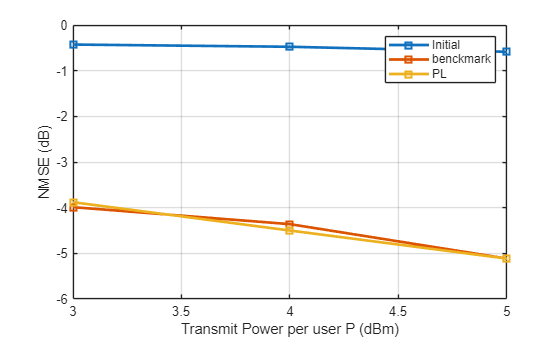

NmsePlot(methods, Pw_user_dBm,NmseVec)

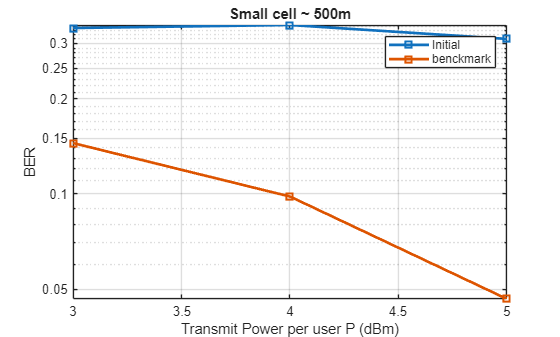

BerPlot(methods, Pw_user_dBm,BerVec);
title('Small cell ~ 500m')

RsumPlot(methods, Pw_user_dBm,RsumVec);

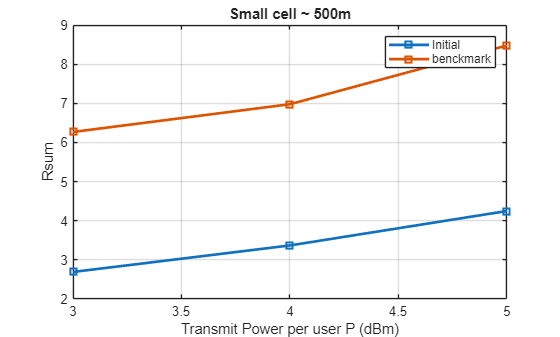

title('Small cell ~ 500m')